Received data formatting to matlab compatibility

clear all;

%%% This script is used to read the binary file produced by the DCA1000
%%% and Mmwave Studio
%fs=10Hz
%no of adc samples=128
%frame duration=100ms( 10 frames in one second)
%no of chirp loop=40
% total observation duration=120 sec, so number of frames=120*10=1200,
% total chirps=1200*40=48000 chirps

numADCSamples = 128; % number of ADC samples per chirp
numADCBits = 16; % number of ADC bits per sample
numRX = 4; % number of receivers
numLanes = 2; % do not change. number of lanes is always 2
isReal = 0; % set to 1 if real only data, 0 if complex data0
% read .bin file
fid = fopen('C:\Users\Anuradha\Desktop\RA_Maori Vital Sign Study\Data Collection Folder\Participant 1\Case1\Data 2\adc_data.bin','r');
% DCA1000 should read in two's complement data
adcData = fread(fid, 'int16');
% if 12 or 14 bits ADC per sample compensate for sign extension 
if numADCBits ~= 16
    l_max = 2^(numADCBits-1)-1;
    adcData(adcData > l_max) = adcData(adcData > l_max) - 2^numADCBits;
end
fclose(fid);
fileSize = size(adcData, 1);
% real data reshape, filesize = numADCSamples*numChirps
if isReal
    numChirps = fileSize/numADCSamples/numRX;
    LVDS = zeros(1, fileSize);
    %create column for each chirp
    LVDS = reshape(adcData, numADCSamples*numRX, numChirps);
    %each row is data from one chirp
    LVDS = LVDS.';
else
% for complex data
% filesize = 2 * numADCSamples*numChirps
numChirps = fileSize/2/numADCSamples/numRX
LVDS = zeros(1, fileSize/2);
%combine real and imaginary part into complex data
%read in file: 2I is followed by 2Q
counter = 1;
for i=1:4:fileSize-1
LVDS(1,counter) = adcData(i) + sqrt(-1)*adcData(i+2); 
LVDS(1,counter+1) = adcData(i+1)+sqrt(-1)*adcData(i+3); counter = counter + 2;
end
LVDS=LVDS(1,1:numChirps*numADCSamples*numRX)
% create column for each chirp
LVDS = reshape(LVDS, numADCSamples*numRX, numChirps);
%each row is data from one chirp
LVDS = LVDS.';
end

numChirps = 48000

LVDS = 1.0e+03 *

  -1.1390 - 0.5450i  -0.1640 - 1.0240i   0.6450 - 0.4720i   0.7920 + 0.6150i  -0.2250 + 1.3470i  -1.4830 + 0.8970i  -1.9800 - 0.3890i  -1.2360 - 1.6140i   0.2540 - 1.7370i   1.0210 - 0.9020i   0.9980 + 0.2340i   0.3340 + 0.8450i  -0.6160 + 0.7090i  -0.9970 - 0.0950i  -0.5830 - 0.7490i   0.1210 - 0.8360i   0.4410 - 0.2300i   0.1550 + 0.3020i  -0.4750 + 0.2440i  -0.7930 - 0.3780i  -0.5850 - 1.2010i   0.3130 - 1.5140i   1.2720 - 1.1270i   1.5670 + 0.0320i   0.8230 + 0.9420i  -0.5710 + 0.7090i  -0.8720 - 0.5410i   0.1350 - 1.4090i   1.2730 - 1.3080i   1.8460 - 0.2530i   1.5690 + 0.7590i   0.7680 + 1.1700i   0.1720 + 1.1720i  -0.1380 + 0.8170i  -0.3600 + 0.5130i  -0.3870 + 0.0640i  -0.2190 - 0.1180i  -0.1250 - 0.2820i   0.1920 - 0.1330i   0.2610 - 0.0360i   0.2190 + 0.0510i   0.2670 + 0.0560i   0.1850 + 0.0140i   0.3470 - 0.2150i   0.8510 - 0.0180i   0.9030 + 0.6600i   0.2740 + 0.9510i  -0.0050 + 0.9360i  -0.1090 + 0.8700i  -0.3320 + 0.9630i


%organize data per RX
adcData = zeros(numRX,numChirps*numADCSamples);
for row = 1:numRX
    for i = 1: numChirps
        adcData(row, (i-1)*numADCSamples+1:i*numADCSamples) = LVDS(i, (row-1)*numADCSamples+1:row*numADCSamples);
    end
end
%% return receiver data
retVal = adcData;

## Beamforming at receiver


% % % Construct the receive array
c=3e8;
fc=77e9;
lambda=c/fc;
Ne = 4;
rxArray = phased.ULA('NumElements',Ne,...
    'ElementSpacing',lambda/2);
% Form forward-facing beam
beamformer = phased.PhaseShiftBeamformer('SensorArray',rxArray,...
    'PropagationSpeed',c,'OperatingFrequency',fc,'Direction',[0;0]);
% Beamform received data
Xbf = beamformer(retVal');
bf_data=Xbf';
% bf_data=retVal(1,:)

## DC Offset correction

% % correct the signal through dc offset correction

Bi = real(bf_data);
Bq = imag(bf_data);
Ar= sqrt(sum((Bi.^2) + (Bq.^2))) ;
fun = @(dc)(abs(sqrt((Bi - dc(1)).^2 + (Bq - dc(2)).^2 ) - dc(3)));
dc0 = [0,0,Ar];
options = optimoptions(@lsqnonlin,'Algorithm','levenberg-marquardt');
dcnew = lsqnonlin(fun,dc0,[],[],options);


Local minimum possible.

lsqnonlin stopped because the final change in the sum of squares relative to 
its initial value is less than the value of the function tolerance.

<stopping criteria details>


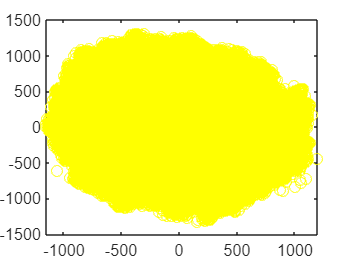

Bin = (Bi-dcnew(1,1));      % for hetrodyne architecture amplitude imabalnce is not needed
Bqn = (Bq-dcnew(1,2));


figure(1);clf
plot(Bq,Bi,'o', "Color",'y');

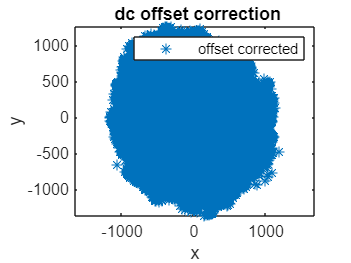

plot(Bqn,Bin,'*');
title(' dc offset correction')
legend('offset corrected')
xlabel x, ylabel y
axis equal


bf_signal_dccorrected = complex(Bin, Bqn);

# %Data Cube Formation


% no of chirps Nchirp
% no of samples in a chirp Nsample
% data cube formation
Nsample=128;
Nrow= round(length(bf_data)/Nsample); %1200
end_val = 0;
data_cube = complex(zeros(Nrow,Nsample));
data_cube_complete = complex(zeros(Nrow,Nsample));
for i = 1:Nrow-1
    init_val = end_val+1;
    end_val = Nsample*i;
    data_cube(i,:) = bf_data(1, init_val:end_val);
 data_cube_complete(i,:) = bf_signal_dccorrected(1, init_val:end_val);
end
data_cube_locs=data_cube_complete(1:40:end,:);

% data_cube_diff = diff(data_cube_locs)

## PHASE EXTRACTION: VITAL SIGNAL

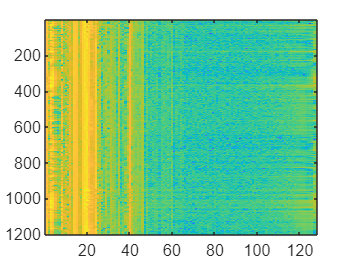

range_slow_mat = fft(data_cube_locs,Nsample,2); % range bin finding through fft on fast time smples
%% Background Substraction

figure(2);
imagesc(mag2db(abs(range_slow_mat)));

pow_range =(abs(range_slow_mat).^2);
mean_pow_range = mean(pow_range);
[pks1,locs1] = max(mean_pow_range(1,1:10));
locs1

locs1 = 3

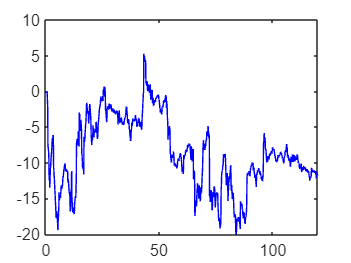

signal_target=range_slow_mat(:,locs1);
sig_i=real(signal_target);
sig_q=imag(signal_target);
[Nrow,~]= size(data_cube_locs);
nmer=zeros(Nrow,1);
dnmer=zeros(Nrow,1);
ph_term=zeros(Nrow,1);
x_phase=zeros(Nrow,1);
    
for k=2:Nrow
    nmer(k)=sig_i(k)*(sig_q(k)-sig_q(k-1))-(sig_i(k)-sig_i(k-1))*sig_q(k);
    dnmer(k)= sig_q(k)^2+sig_i(k)^2;
    ph_term(k)=nmer(k)/dnmer(k);
end
for n=2:Nrow
    x_phase(n)=sum(ph_term(2:n));
end
   
fs=10;
N = length(x_phase);
t = (0:N-1)/fs;         % time axis
figure(5);clf
plot(t,x_phase,'b')